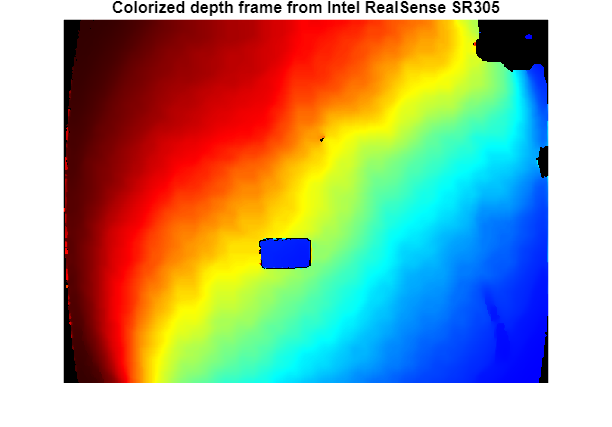

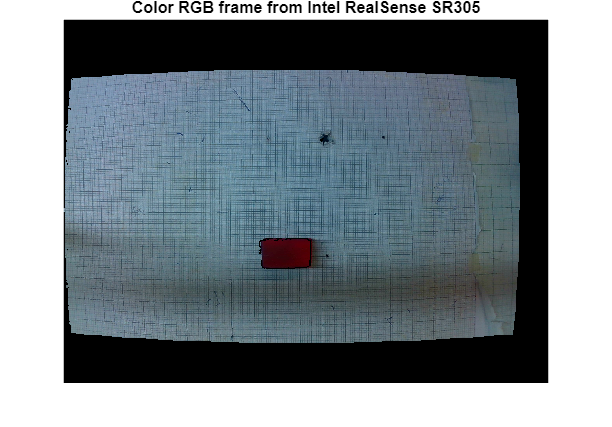

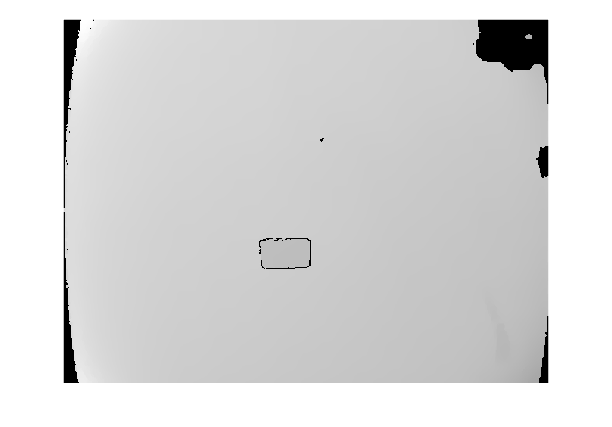

%% -------------------- 1. Load and Synchronize Resolutions --------------------
clc; clear; close all;

[imgDepth, imgRGB] = depth_example();


[rows, cols, ~] = size(imgRGB); 

% Resize depth image
imgDepth = imresize(imgDepth, [rows, cols], 'nearest');
depthData = double(imgDepth);

% Synchronize dimensions
[dRows, dCols] = size(depthData);
rows = min(rows, dRows);
cols = min(cols, dCols);
imgRGB = imgRGB(1:rows, 1:cols, :);
depthData = depthData(1:rows, 1:cols);

%% -------------------- 2. Segment Red Block --------------------
imgLab = rgb2lab(imgRGB);
[L, a, b] = imsplit(imgLab);

redMask = a > 20 & b > 10; 
redMask = imclose(redMask, strel('disk', 5)); 
redMask = bwareaopen(redMask, 500); 

%% -------------------- 3. PCA for Rectified Orientation --------------------
[row_pixels, col_pixels] = find(redMask); 
pixel_coords = [col_pixels, row_pixels]; 
coeff = pca(pixel_coords); 

x_vec = coeff(:,2); % Minor Axis
y_vec = coeff(:,1); % Major Axis

if det([x_vec, y_vec]) < 0
    y_vec = -y_vec;
end

%% -------------------- 4. Depth and Center Logic (Integrated) --------------------
fx = 475.2710; fy = 475.2711; 
cx_img = 316.3301; cy_img = 245.5315;

% --- Optimized PCA-based Bounding Box ---
% Use the pixel coordinates already found in Section 3
mu = mean(pixel_coords, 1);
centered_points = pixel_coords - mu;

% Project the block pixels onto the PCA axes (Principal Components)
proj = centered_points * [x_vec, y_vec]; 
min_p = min(proj); max_p = max(proj);

% Define 4 corners in the local (aligned) coordinate system
corners_local = [min_p(1), min_p(2); 
                 max_p(1), min_p(2); 
                 max_p(1), max_p(2); 
                 min_p(1), max_p(2); 
                 min_p(1), min_p(2)]; 

% Rotate corners back to the image pixel frame
corners_img = corners_local * [x_vec, y_vec]' + mu;

rect_x = corners_img(:, 1);
rect_y = corners_img(:, 2);

% Precise centroid for the Transformation Matrix
perfect_cx = mu(1); 
perfect_cy = mu(2);

% Faster depth calculation (Vectorized)
height_vals = imgDepth(redMask > 0);
Z = median(height_vals(height_vals > 0)) * 100;

% Precise X and Y
X = (perfect_cx - cx_img) * Z / fx;
Y = (perfect_cy - cy_img) * Z / fy;

%% -------------------- 5. Final 4x4 Transformation Matrix --------------------
R_cb = [ x_vec(1),  y_vec(1),  0;
         x_vec(2),  y_vec(2),  0;
         0,         0,         1];

T_cb = [R_cb, [X; Y; Z]; 0, 0, 0, 1];

disp('--- Rectified 4x4 Transformation Matrix ---');

--- Rectified 4x4 Transformation Matrix ---


disp(T_cb);

   -0.0881   -0.9961         0   -1.1536
    0.9961   -0.0881         0    4.9622
         0         0    1.0000   37.1585
         0         0         0    1.0000



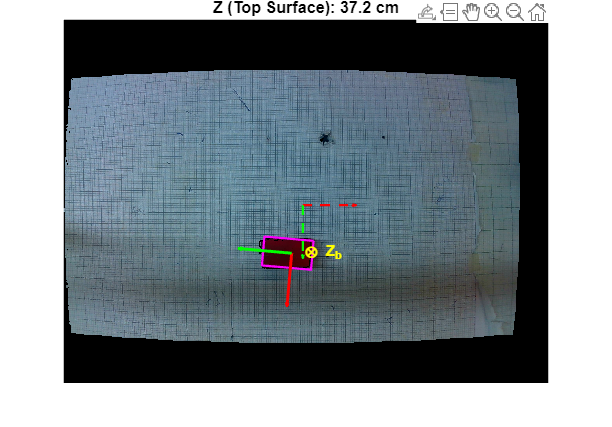


%% -------------------- 6. Visualization --------------------
figure('Name', 'Rectified Block Frame');
imshow(imgRGB); hold on;
plot(rect_x, rect_y, 'm', 'LineWidth', 1.5); % Bounding box
axisLen = 70;

% Block Frame
quiver(perfect_cx, perfect_cy, axisLen*x_vec(1), axisLen*x_vec(2), 0, 'r', 'LineWidth', 2); 
quiver(perfect_cx, perfect_cy, axisLen*y_vec(1), axisLen*y_vec(2), 0, 'g', 'LineWidth', 2); 
text(perfect_cx, perfect_cy, ' \otimes Z_b', 'Color', 'y', 'FontSize', 10, 'FontWeight', 'bold');

% Camera Frame
quiver(cx_img, cy_img, axisLen, 0, 0, 'r', 'LineWidth', 1.5, 'LineStyle', '--'); 
quiver(cx_img, cy_img, 0, axisLen, 0, 'g', 'LineWidth', 1.5, 'LineStyle', '--'); 

title(sprintf('Z (Top Surface): %.1f cm', Z));
hold off;